# State Space Descriptions: Criteria and Examples

## Introduction

This live script uses Matlab and Simulink to implement a state space description for a dynamical (linear or nonlinear, time-invariant or time-variant, continuous or discrete time) system.

What you will learn: 

- Given a state space description of a dynamical system, how to build a Simulink model for such a system;

- Tune a Simulink model, setting the model parameters (or the simulation parameters) using a Matlab script;

- How to run a Simulink model and retrieve the results using a Matlab script.

## Modeling Based on Conservation Balances

The dynamics of the system is given by the state-space model derived from conservation balances (of mass, energy, etc.).

### A Nonlinear Continuous Time System: a Continuous Bio-Reactor

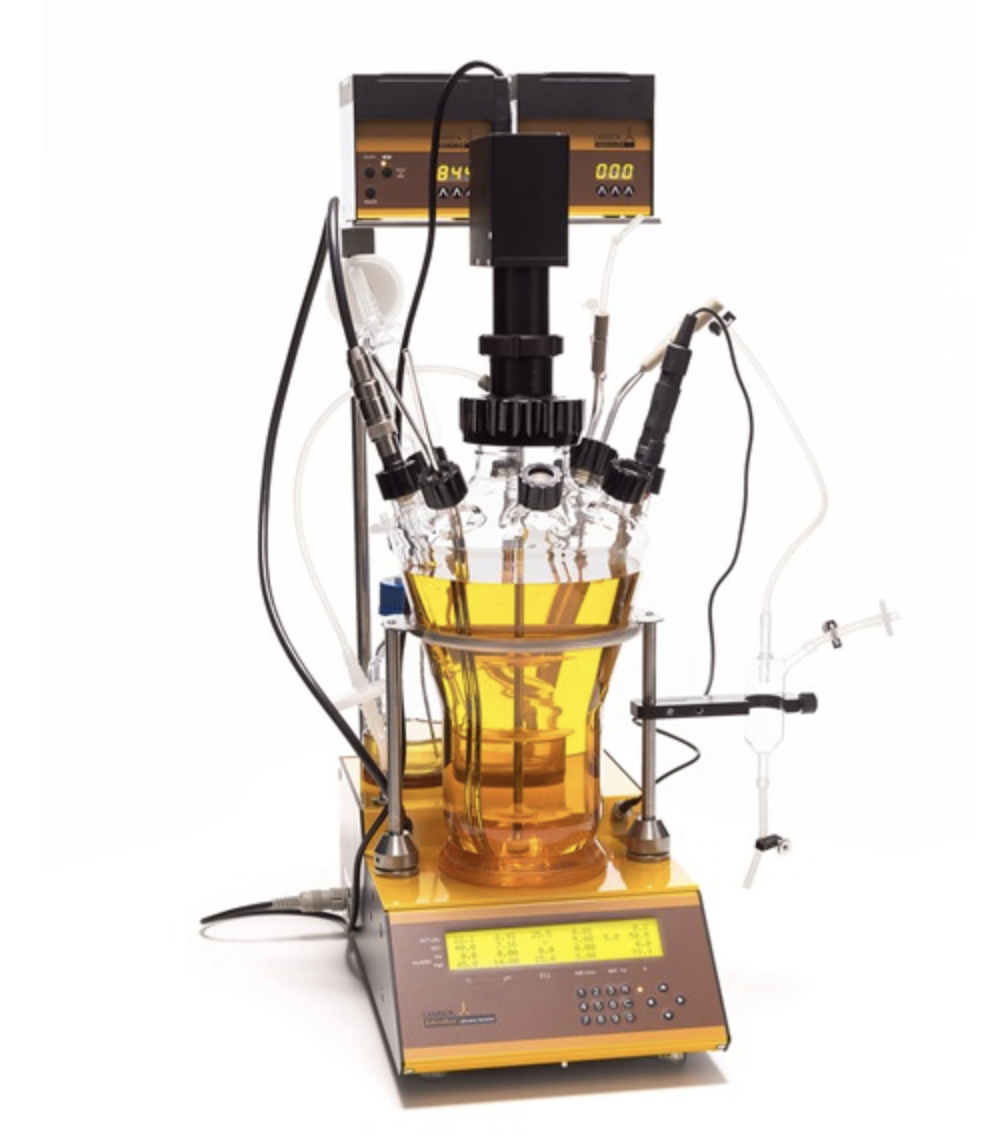

Example of fermenter-bioreactor (Source: LAMBDA Instruments)

The dynamics of the process are derived from the conservation balances for the biomass with concentration $x_1$and substrate mass with concentration $x_2$


$$\left\{ \begin{array}{lcl}
\displaystyle \dot{x}_1(t) &=& \mu \left( x_2(t) \right) \cdot x_1(t) - \displaystyle \frac{x_1(t) \cdot  u(t)}{V} \\[0.5em]
\dot{x}_2(t) &=& -\displaystyle \frac{\mu\left( x_2(t) \right) \cdot x_1(t)}{Y} + \frac{\left(S_{F}-x_2(t)\right) \cdot u(t)}{V} \\[0.5em]
y_1(t) &=& x_1(t) \\[0.5em]
y_2(t) &=& x_2(t) 
\end{array} \right. \quad \text{where} \qquad \mu\left(x_2(t)\right) = \mu_{\text{max}} \cdot \displaystyle \frac{x_2(t)}{K_2 x_2^2(t) + x_2(t)+K_1}$$


where

- $x_1$ is the biomass concentration [g/f];

- $x_2$ is the substrate concentration [g/l];

- $u$ is the feed flow rate [l/h]

and the parameters assume the following values

- volume $V$:  $V= 4 \; \text{[l]}$

- substrate feed concentration $S_F$: $S_{F} = 10 \; \text{[g/l]}$

- yield coefficient $Y
$: $Y = 0.5 \; \text{ [-]}$

- maximal grow rate $\mu_{\text{max}}$: $\mu_{\text{max}} = 1 \; \text{[l/h]}$

- saturation parameter $K_1$: $K_1 = 0.03 \; \text{[g/l]}$

- inhibition parameter $K_2$: $K_2 = 0.5 \; \text{[l/g]}$

### Cleaning the Matlab Workspace

close all
clear
clc


#### Assigning the System Parameters

V = 4;     % volume [l]
S_F = 10;  % substrate feed concentratiion [g/l]
Y = 0.5;   % yield coefficient
muMAX = 1; % maximal grow rate [l/h]
K1 = 0.03; % saturation parameter [g/l]
K2 = 0.5;  % inhibition parameter [g/l]

#### Initial Condition and Input Configuration

x2_0 = -(K1 - (K1*(K2*S_F^2 + S_F + K1))^(1/2))/(K2*S_F + 1); % initial substrate concentration [g/l]
x1_0 =(S_F-x2_0)*Y;                                           % initial biomass concentration [g/l]

u_M = V*muMAX*x2_0/(K2*x2_0^2+x2_0+K1);     % mean input flow rate [l/h]
                                          % the input flow rate is a sinusoidal function with
                                          % amplitude 1.0 and time period 0.5 h
u_A = 0.75e-3;    % amplitude of the square wave input component [l/h]
T_u = 2.5 * 3600; % time period of the periodic input component [seconds]
Tp = 120;         % the time constant of the 1.st order LP filter, used to smooth the input

#### Simulation Time Interval

T_start = 0.0;        % starting time instant
T_stop = 10.0 * 3600; % end of the simulation after 6 h

#### The Simulink Model

open_system("BioReactor_model.slx"); 
% Loading the Simulink model (it may take a few seconds at the first
% loading of the Simulink model).

#### Simulation of the System

simOut = sim("BioReactor_model.slx");
% let us run Simulink model and retrieve the results
U,0
data = simOut.find('yout'); % the result of the simulation: see the Simulink model
                               % y1_y2_u(:,1) <--> y_1
                               % y1_y2_u(:,2) <--> y_2
                               % y1_y2_u(:,3) <--> u
y_out = data(:,1); % the model output y_1
y2 = data(:,2); % the model output y_2
u = data(:,3);   % the model input u

t_stamps = simOut.tout/3600; % time instants [h]
% time instants corresponding to the solution samples 

#### Retrieving and Showing the Result

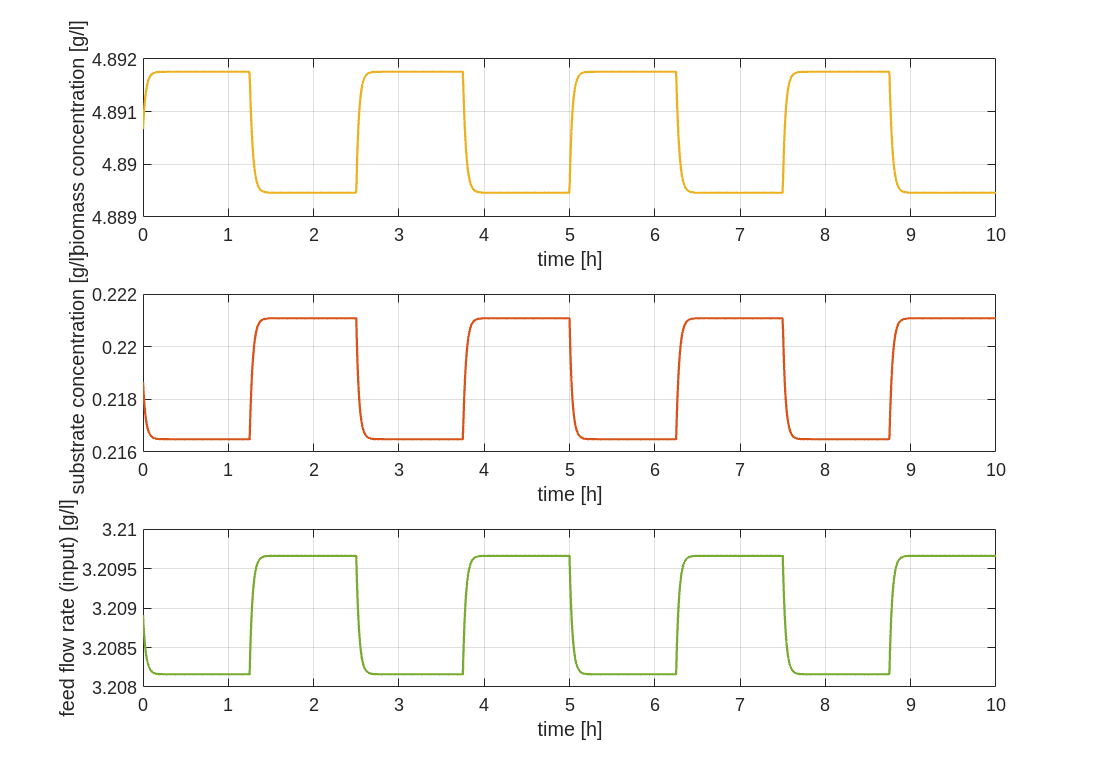

figure('Name','Bioreactor Simulation','Units','normalized','Position',[0.1, 0.1, 0.75, 0.95]);
h1 = subplot(3,1,1);
plot(t_stamps, y_out, 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250]); % bioreactor outputs y_1 vs time
xlabel('time [h]'); ylabel('biomass concentration [g/l]'); % labels on the plot axes
grid on; 
tMIN = min(t_stamps); tMAX = max(t_stamps);
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);

h2 = subplot(3,1,2);
plot(t_stamps, y2, 'LineWidth',2, 'Color',[0.8500 0.3250 0.0980]); % bioreactor outputs y_2 vs time
xlabel('time [h]'); ylabel('substrate concentration [g/l]'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);

h3 = subplot(3,1,3);
plot(t_stamps, u, 'LineWidth',2, 'Color',[0.4660 0.6740 0.1880]); % bioreactor outputs y_2 vs time
xlabel('time [h]'); ylabel('feed flow rate (input) [g/l]'); % labels on the plot axes
grid on;currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);

linkaxes([h1 h2 h3], 'x');

#### Closing the Model

close_system("BioReactor_model.slx");
close all
clear
clc

uiwait(msgbox(["BioReactor_model - Simulation Completed"; ...
                "Close This Window to Continue!"],"Success","help", "modal"));


## Modeling Based on Input-Output Mathematical Description

The state-space model is derived from an input/output model based on differential equations or from an in-out diifference equation model.

### A Nonlinear Continuous Time System: a Second Order Ordinary Differential Equation

Let us consider the nonlinear dynamical system defined by the differential equation


$$\ddot{y}(t) +\alpha_1 \dot{y}(t) +\alpha_0 y(t)\cdot \left[1+\gamma_1 y^{2}(t)\right] = \beta_0 \left[ 1+\gamma_2 y(t) \right] \cdot u(t)$$


This model can be expressed in state-space form as


$$\left\{\begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\[0.5em]
\dot{x}_2(t) 
\end{array} \right] &=& \left[ \begin{array}{c}
x_2(t) \\[0.5em]
f\left(x_1(t)\,,\; x_2(t)\,,\; u(t)\right) 
\end{array} \right] \\[0.75em]
y(t) &=& x_1(t)
\end{array} \right.$$


where


$$f\left(x_1(t)\,,\; x_2(t)\,,\; u(t) \right) = -\alpha_1 x_2(t) -\alpha_0 x_1(t)\cdot \left[1+\gamma_1 x_1^2(t) \right] +\beta_0 \left[1+\gamma_2 x_1(t)\right]\cdot u(t)$$


#### Parameters

Assume the following values for the differential equation parameters:

- 
$$\alpha_1 = 3\,,\; \alpha_0 = 2\,,\; \gamma_1 = 0.5$$


- 
$$\beta_0 = 2\,,\; \gamma_2 = 0.25$$


#### Initial values

Moreover, the initial values for the state variables are

- 
$$x_1(0) = y(0) = +2.50$$


- 
$$x_2(0) = \dot{y}(0) = -24.48$$


#### Input

Finally the input is


$$u(t) = e^{-4\,t}\cdot \left[2.50 \sin(3\,t)-7.25 \cos(2\,t) \right]\cdot 1(t)$$


### Cleaning the Matlab Workspace

close all
clear
clc


#### Assigning the System Parameters

alpha1 = 3.0;  %#ok<*NASGU> 
alpha0 = 2.0;  
gamma1 = 0.5;  
beta0 = 2.0; 
gamma2 = 0.25; 

#### Initial Condition and Input Configuration

x1_0 =  +2.50; % initial value of the 1st state variable
x2_0 = -24.48; % initial value of the 2nd state variable

u_expT = 1/4;  % time constant of the exponential input component
u_sinA = 2.50; % amplitude of the sinusoidal input component
u_sinO = 3.0;  % angular frequency of the input sinusoidal component [rad/s]
u_cosA = 7.25; % amplitude of the cosinusoidal input component
u_cosO = 2.0;  % angular frequency of the input cosinusoidal component [rad/s]


#### Simulation Time Interval

T_start = 0.0; % starting time instant [s]
T_stop = 25.0; % end of the simulation  [s]

#### The Simulink Model

open_system("StateSpace_from_ODE.slx"); 
% Loading the Simulink model (it may take a few seconds at the first
% loading of the Simulink model).


#### Simulation of the System

simOut = sim("StateSpace_from_ODE.slx");
% let us run Simulink model and retrieve the results

data = simOut.find('yout'); % the result of the simulation: see the Simulink model
                               % data(:,1) <--> y
                               % data(:,2) <--> u
y_out = data(:,1); % the model output y_1
u = data(:,2);   % the model input u

stateVar = simOut.find('xout'); % the result of the simulation: see the Simulink model
                               % stateVar(:,1) <--> x_1
                               % stateVar(:,2) <--> x_2
x_1 = stateVar(:,1); % 1st state variable: x_1(t) <--> y(t)
x_2 = stateVar(:,2); % 2nd state variable: x_2(t) <--> dot_y(y)

t_stamps = simOut.tout; % time instants [s]
% time instants corresponding to the solution samples 


#### Retrieving and Showing the Result

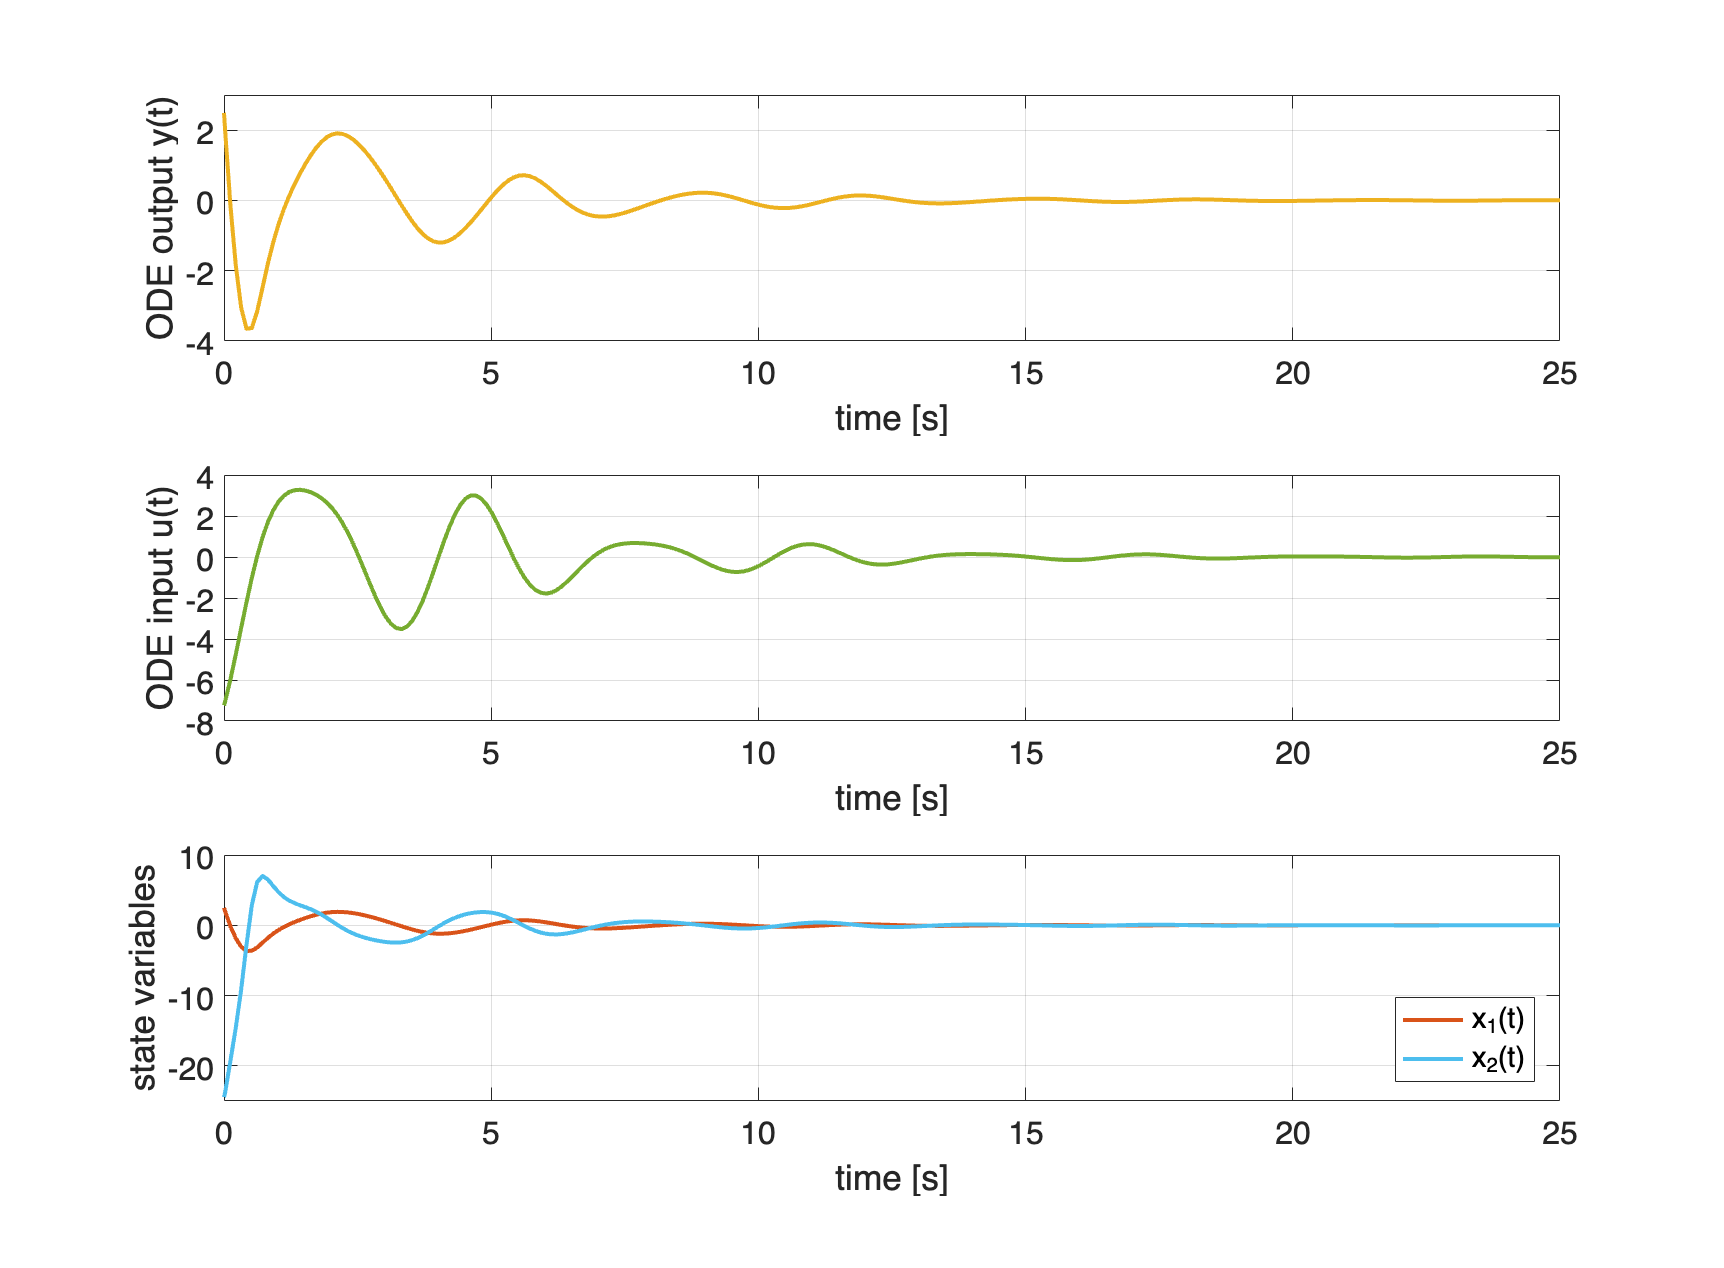

figure('Name','State-Space from ODE','Units','normalized','Position',[0.1, 0.1, 0.65, 0.85]);
h1 = subplot(3,1,1);
plot(t_stamps, y_out, 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250]); % ODE output vs time 
xlabel('time [s]'); ylabel('ODE output y(t)'); % labels on the plot axes
grid on; 
tMIN = min(t_stamps); tMAX = max(t_stamps);
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);

h2 = subplot(3,1,2);
plot(t_stamps, u, 'LineWidth',2, 'Color',[0.4660 0.6740 0.1880]); % bioreactor outputs y_2 vs time
xlabel('time [s]'); ylabel('ODE input u(t)'); % labels on the plot axes
grid on;currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);

h3 = subplot(3,1,3);
plot(t_stamps, x_1, 'LineWidth',2, 'Color',[0.8500 0.3250 0.0980]); % state variable x_1
hold on;
plot(t_stamps, x_2, 'LineWidth',2, 'Color',[0.3010 0.7450 0.9330]); % state variable x_2
xlabel('time [s]'); ylabel('state variables'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);
legend('x_1(t)', 'x_2(t)', 'Location','best');
linkaxes([h1 h2 h3], 'x');

#### Closing the Model

close_system("StateSpace_from_ODE.slx");
close all
clear
clc

uiwait(msgbox("StateSpace_from_ODE - Simulation Completed","Success","help", "modal"));

### A Nonlinear Discrete Time System: a Third Order Difference Equation

Let us consider the nonlinear dynamical system defined by the difference equation


$$y(k+1) = \displaystyle \frac{y(k) y(k-1) y(k-2) \big( y(k-2)-1 \big) u(k-1)+u(k)}{1+y^{2}(k-1)+y^{2}(k-2)} \;,\quad k \ge 2$$


with initial conditions


$$y(0) = +2.10 \;,\quad y(1) = -3.40\;, \quad y(2)= +0.25$$


and the input sequence 


$$u(k) = \big[\sin \big( 3\,k \big)+\sin\big(0.25\,k\big)-\cos\big(40\,k\big) \big]\cdot 1(k)$$


This model can be expressed in state-space form as


$$\left\{ \begin{array}{lcl}
\left[ \begin{array}{c}
x_1(k+1) \\
x_2(k+1)\\
x_3(k+1) 
\end{array} \right] &=& \left[ \begin{array}{c}
x_2(k) \\ x_3(k) \\ \varphi \big(x_1\,,\; x_2\,,\; x_3\,,\; u \,,\; k \big)
\end{array} \right]\\
y(k) &=& x_3(k)
\end{array} \right.$$


where


$$ \varphi \big(x_1\,,\; x_2\,,\; x_3\,,\; u\,,\; k  \big) = \displaystyle \frac{x_3(k)\cdot x_2(k) \cdot x_1(k) \cdot \big[x_1(k)-1\big] \cdot u(k-1)+u(k)}{1+x^{2}_2(k)+x^{2}_1(k)} $$


### Cleaning the Matlab Workspace

close all
clear
clc


#### Assigning the Initial Condition and Input Configuration

x1_0 = +2.10; % initial value of the 1st state variable x1(k) <--> y(k-2)
x2_0 = -3.40; % initial value of the 2nd state variable x2(k) <--> y(k-1)
x3_0 = +0.25; % initial value of the 3rd state variable x3(k) <--> y(k)

u_Om1 = 3.00; % angular frequency of the 1st input sinusoidal component [rad/sample]
u_Om2 = 0.25; % angular frequency of the 2nd input sinusoidal component [rad/sample]
u_Om3 = 40.0; % angular frequency of the 3rd input sinusoidal component [rad/sample]


#### Simulation Time Interval

T_start = 0.0; % starting time instant [s]
T_stop = 1250.0; % end of the simulation  [s]
Ts = 1; % discrete time period [s]

#### The Simulink Model

open_system("StateSpace_DifferenceEq.slx"); 
% Loading the Simulink model (it may take a few seconds at the first
% loading of the Simulink model).


#### Simulation of the System

simOut = sim("StateSpace_DifferenceEq.slx");
% let us run Simulink model and retrieve the results

data = simOut.find('yout'); % the result of the simulation: see the Simulink model
                               % data(:,1) <--> y
                               % data(:,2) <--> u
y_out = data(:,1); % the model output y_1
u_in = data(:,2);   % the model input u

stateVar = simOut.find('xout'); % the result of the simulation: see the Simulink model
                               % stateVar(:,1) <--> x_1
                               % stateVar(:,2) <--> x_2
x_1 = stateVar(:,1); % 1st state variable: x_1(k) <--> y(k-2)
x_2 = stateVar(:,2); % 2nd state variable: x_2(k) <--> y(k-1)
x_3 = stateVar(:,3); % 2nd state variable: x_2(k) <--> y(k)

t_stamps = simOut.tout; % time instants [s]
% time instants corresponding to the solution samples 


#### Retrieving and Showing the Result

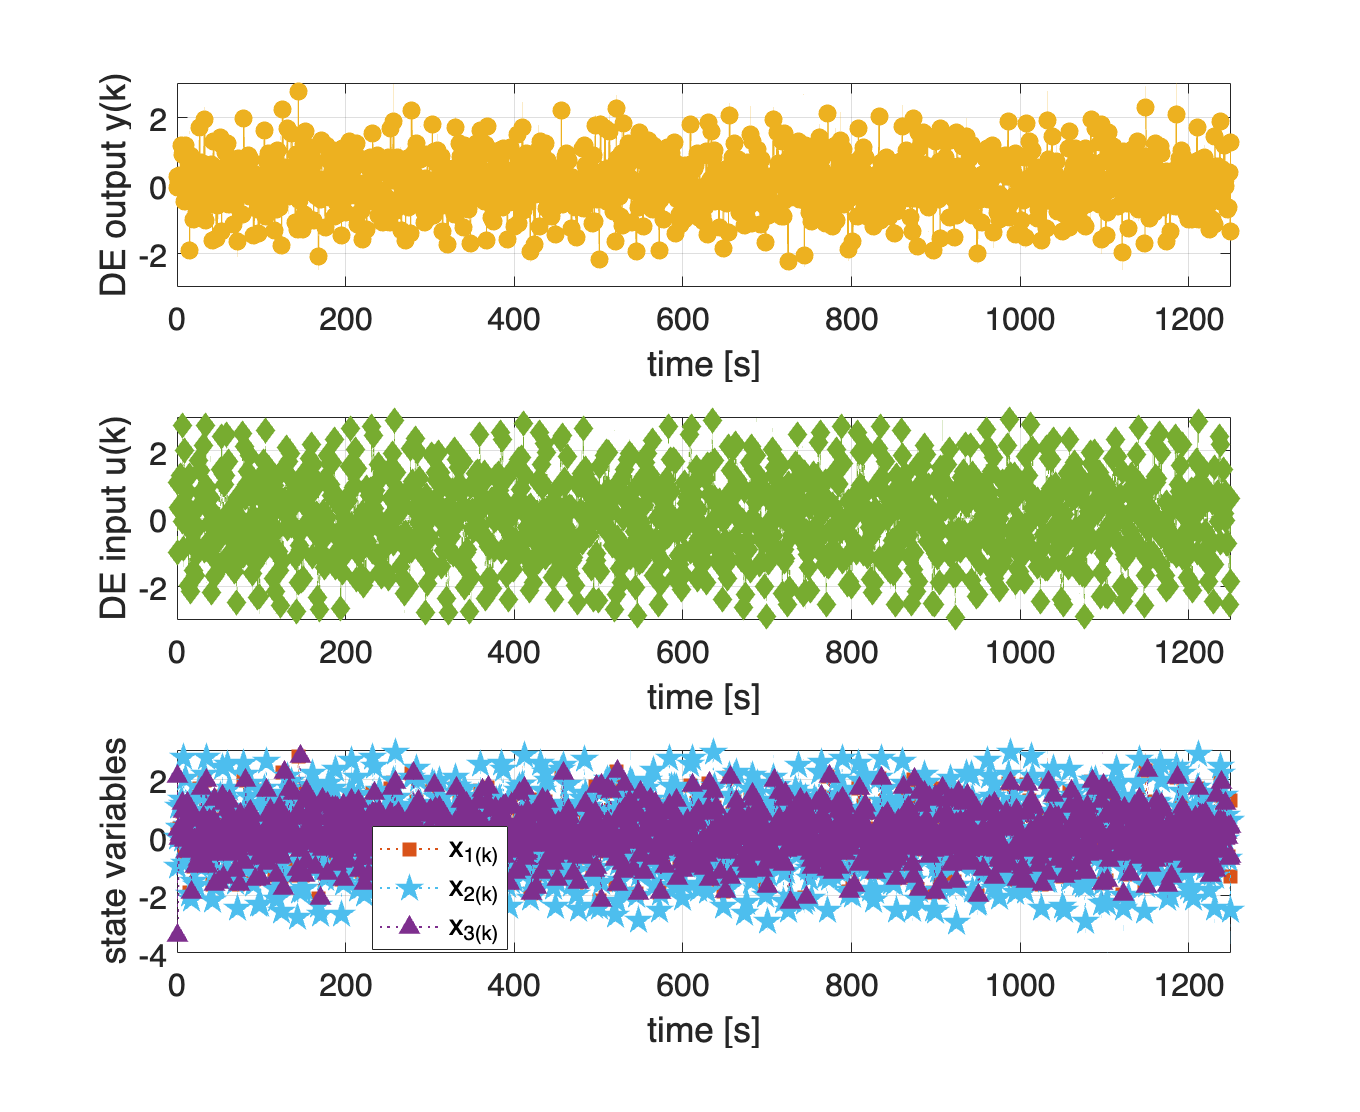

figure('Name','State-Space from Difference Equations','Units','normalized','Position',[0.1, 0.1, 0.65, 0.85]);
h1 = subplot(3,1,1);
plot(t_stamps, y_out, 'lineStyle', ' -', 'LineWidth', 1, 'Marker', 'o', 'Color',[0.9290 0.6940 0.1250], ...
     'MarkerSize', 8,  'MarkerFaceColor',[0.9290 0.6940 0.1250], 'MarkerEdgeColor', [0.9290 0.6940 0.1250]); % Diff. Eq output vs time 
xlabel('time [s]'); ylabel('DE output y(k)'); % labels on the plot axes
grid on; 
tMIN = min(t_stamps); tMAX = max(t_stamps);
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);

h2 = subplot(3,1,2);
plot(t_stamps, u_in, 'LineStyle', '-.', 'LineWidth',1, 'Color',[0.4660 0.6740 0.1880], ...
    'Marker', 'diamond', 'MarkerSize',8,'MarkerFaceColor',[0.4660 0.6740 0.1880],...
    'MarkerEdgeColor',[0.4660 0.6740 0.1880]); % bioreactor outputs y_2 vs time
xlabel('time [s]'); ylabel('DE input u(k)'); % labels on the plot axes
grid on;currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 16);

h3 = subplot(3,1,3);
plot(t_stamps, x_1, 'LineStyle', ':', 'LineWidth', 1,'Color',[0.8500 0.3250 0.0980], ...
    'Marker','square','MarkerSize', 8, 'MarkerFaceColor', [0.8500 0.3250 0.0980], 'MarkerEdgeColor',[0.8500 0.3250 0.0980]); % state variable x_1
hold on;
plot(t_stamps, x_2,'LineStyle', ':', 'LineWidth', 1,'Color',[0.3010 0.7450 0.9330],...
    'Marker','pentagram','MarkerSize', 12, 'MarkerFaceColor', [0.3010 0.7450 0.9330], 'MarkerEdgeColor', [0.3010 0.7450 0.9330]); % state variable x_2
plot(t_stamps, x_3,'LineStyle', ':', 'LineWidth', 1,'Color',[0.4940 0.1840 0.5560],...
    'Marker',  '^','MarkerSize', 8, 'MarkerFaceColor', [0.4940 0.1840 0.5560], 'MarkerEdgeColor', [0.4940 0.1840 0.5560]); % state variable x_2
xlabel('time [s]'); ylabel('state variables'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);
legend('x_1(k)', 'x_2(k)', 'x_3(k)', 'Location','best');
linkaxes([h1 h2 h3], 'x');set(gca, 'FontSize', 16);

#### Closing the Model

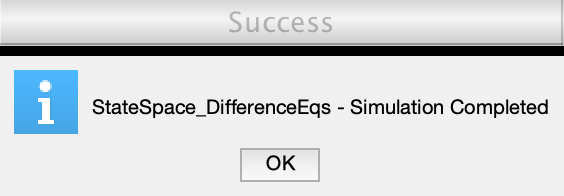

close_system("StateSpace_DifferenceEq.slx");
close all
clear
clc


msgbox("StateSpace_DifferenceEqs - Simulation Completed","Success","help", "modal")

## A Proposal

Using what is shown in this live script, create the Simulink models and write the Matlab code necessary to configure them, run the simulation and retrieve the results, for the examples proposed in the live script named [StateSpaceDescription_Exercises.mlx](matlab:open('./StateSpaceDescription_Exercises.mlx'))